Conexion ThingSpeaking

  
% Channel ID to read data from 
readChannelID = 2013619;  
% Channel Read API Key      
readAPIKey = 'E9C9I4JBQOEUSETJ';  
% Channel Read API Key      
writeAPIKey = 'G28HZOKZQFENE9K6';     
 

Obtencion de datos, son los valores enviados por telegram a thingSpeak

estado='inicio';
U = matlab.net.URI('http://169.51.207.249:30664');
U.Query = matlab.net.QueryParameter('payload',estado);
U.Path = 'prueba';
dataW=estado;
rsponseData = thingSpeakWrite(readChannelID,'Fields',2,'Values',{dataW},'WriteKey',writeAPIKey);
webread(U)

ans = struct with fields:
    payload: 'inicio'


  dataFieldID = 1; 
% Fetch dat for the last 10 points from the Telegram 
data = thingSpeakRead(readChannelID,'Fields',dataFieldID,...
'NumMinutes',10,'ReadKey',readAPIKey,'OutputFormat','timetable')

data = 3×1 timetable
         Timestamps                                   NodeR                          
    ____________________    _________________________________________________________

    02-Feb-2023 18:35:03    {'AAG97MIEfgbXTVW7FU6q6Zvz2GuGi2TG1X0,voice,file_25.oga'}
    02-Feb-2023 18:42:16    {'Operar'                                               }
    02-Feb-2023 18:42:56    {'AAG97MIEfgbXTVW7FU6q6Zvz2GuGi2TG1X0,voice,file_26.oga'}


**dataW** es el dato que se envia a thingSpeak, en este caso asigna el ultimom valor de data

%dataW= cell2mat( data.NodeR(length(data.NodeR)) ); 


%clc,clear

**audios**

urlBase='https://api.telegram.org/file/bot5947376359:';
urlAudio=data.NodeR(length(data.NodeR));
urlAudio=cell2mat(urlAudio);
urlAudio=mat2str(urlAudio);
urlAudio=erase(urlAudio,"'");
urlAudio=split(urlAudio,",");
urlAudio=strcat(urlBase,urlAudio(1),"/",urlAudio(2),"/",urlAudio(3));

Descarga de audio,cargue en dos variables **y_audio,  Fs_audio**

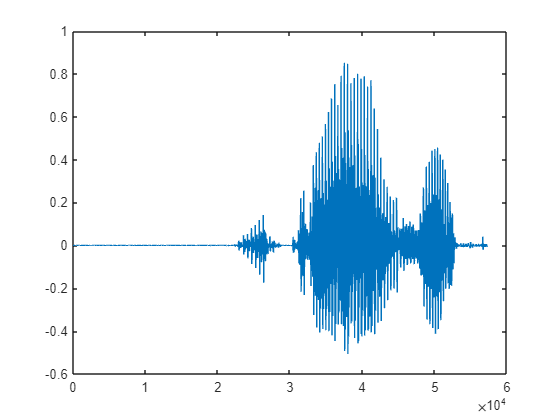

%web(fullfile(docroot, 'matlab/ref/audioread.html?s_tid=doc_ta'))
audioFile = "audio.oga";
imageFileFullPath = websave(audioFile, urlAudio);
[y_audio,Fs_audio] = audioread(audioFile,'native');
plot(y_audio)